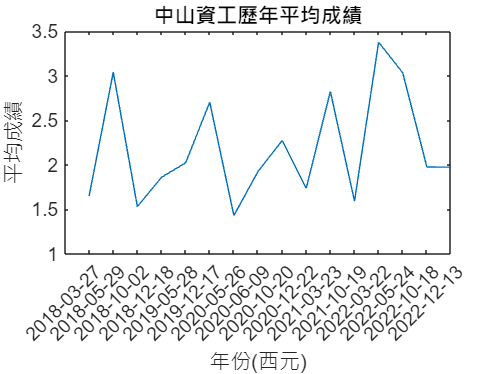

urls = ["2022-12-13", "2022-10-18", "2022-05-24", "2022-03-22", "2021-10-19", "2021-03-23", "2020-12-22", "2020-10-20", "2020-06-09", "2020-05-26", "2019-12-17", "2019-05-28", "2018-12-18", "2018-10-02", "2018-05-29", "2018-03-27"];
filteredData_ntou = cell(1, length(urls));
ntou_avg = zeros(1, length(urls));
for i = 1:length(urls)
    link = "https://cpe.cse.nsysu.edu.tw/cpe/scoreboard/";
    data = readtable(link + urls(i), 'FileType', 'html', 'ReadVariableNames', true, 'ThousandsSeparator', ',');
    data.Properties.VariableNames{2} = 'school';
    data.Properties.VariableNames{4} = 'score';
    filteredData_ntou{i} = data(data.school == "中山資工", :);
    ntou_avg(i) = sum(filteredData_ntou{i}.score) / size(filteredData_ntou{i}, 1);
    plot(flip(ntou_avg))
    xlabel('年份(西元)');
    xticks([1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16]);
    xticklabels(["2018-03-27"	"2018-05-29"	"2018-10-02"	"2018-12-18"	"2019-05-28"	"2019-12-17"	"2020-05-26"	"2020-06-09"	"2020-10-20"	"2020-12-22"	"2021-03-23"	"2021-10-19"	"2022-03-22"	"2022-05-24"	"2022-10-18"	"2022-12-13"]);
    ylabel('平均成績');
    title('中山資工歷年平均成績')
end

url = "https://cpe.cse.nsysu.edu.tw/cpe/scoreboard";
code = webread(url);
tree = htmlTree(code);
selector = "A";
subtrees = findElement(tree,selector);
date = extractHTMLText(subtrees);
As = [];
start = length(date);
otherSchool = ["臺大", "清大", "陽明交大", "成大", "中央", "中興", "中正", "中山", "海洋"];

for i = length(date)-2:length(date)
    %disp(date(i));
    url = 'https://cpe.cse.nsysu.edu.tw/cpe/scoreboard/' + date(i);
    %disp(url);
    data = readtable(url, FileType="html", ReadVariableNames=true, ThousandsSeparator=",");
    % 欄位命名
    data.Properties.VariableNames(1) = "rank";
    data.Properties.VariableNames(2) = "school";
    data.Properties.VariableNames(3) = "studentName";
    data.Properties.VariableNames(4) = "problemSolve";
    % 資料清洗
    hasnan = (isnan(data.rank)|isnan(data.problemSolve));
    data = data(~hasnan, :);

    ntouProblemSolve  = data(data.school == "海洋資工",{'school' 'problemSolve'});
    otherProblemSolve = data(contains(data.school, otherSchool),{'school' 'problemSolve'});

    solve = data.problemSolve;
    schools = data.school;
    school = unique(schools);
    numOfproblemSolveInSchool = zeros(length(school), 1);
    numOfstudentsInSchool = zeros(length(school), 1);
    
    numRows = height(data)
    for j = 1:numRows
        schoolIdx =  find(strcmp(school, schools(j)));
        numOfproblemSolveInSchool(schoolIdx) = numOfproblemSolveInSchool(schoolIdx) + solve(j);
        numOfstudentsInSchool(schoolIdx) = numOfstudentsInSchool(schoolIdx) + 1;
    end
    average = numOfproblemSolveInSchool ./ numOfstudentsInSchool;
    allSchoolAverage = table(average, numOfstudentsInSchool, 'RowNames', school)

    rowNames = data.Properties.RowNames;
    matchIndices = contains(school, otherSchool);
    goodSchoolAverage = allSchoolAverage(matchIndices, :)
    
    matchIndices =  contains(school, otherSchool) &  contains(school, "資工");
    goodCSSchoolAverage = allSchoolAverage(matchIndices, :)
end

numRows = 2352

allSchoolAverage = 160×2 table
               average    numOfstudentsInSchool
               _______    _____________________

    世新資管         1               1          
    中原資工       2.5               2          
    中央太科         2               2          
    中央數學       2.5               2          
    中央機械         3               1          
    中央財金         3               1          
    中央資工    2.5714              42          
    中央資管         2               1          
    中央資電         3               1          
    中央電機    3.3333               3          
    中山人科       1.5               2          
    中山企管       0.5               2          
    中山光工         1               1         

goodSchoolAverage = 53×2 table
               average    numOfstudentsInSchool
               _______    _____________________

    中央太科         2               2          
    中央數學       2.5               2          
    中央機械         3               1          
    中央財金         3               1          
    中央資工    2.5714              42          
    中央資管         2               1          
    中央資電         3               1          
    中央電機    3.3333               3          
    中山人科       1.5               2          
    中山企管       0.5               2          
    中山光工         1               1          
    中山應數       1.2               5          
    中山政經       1.5               2         

goodCSSchoolAverage = 9×2 table
                  average    numOfstudentsInSchool
                  _______    _____________________

    中央資工       2.5714              42          
    中山資工       1.9733              75          
    中正資工       2.7647              17          
    中興資工       2.3636              11          
    成大資工            3               3          
    海洋資工       2.4909              55          
    清大資工            7               1          
    臺大資工          2.9              10          
    陽明交大資工    2.4667              30          


numRows = 2505

allSchoolAverage = 187×2 table
               average    numOfstudentsInSchool
               _______    _____________________

    世新資管         0               1          
    中原應數         1               1          
    中原資工         0               1          
    中原資管         1               1          
    中央企管         1               1          
    中央數學         4               1          
    中央機械         4               1          
    中央英語         0               1          
    中央財金         4               1          
    中央資工    2.6216              74          
    中央資管         3               3          
    中央資電         2               2          
    中央電機       1.6               5         

goodSchoolAverage = 66×2 table
               average    numOfstudentsInSchool
               _______    _____________________

    中央企管         1               1          
    中央數學         4               1          
    中央機械         4               1          
    中央英語         0               1          
    中央財金         4               1          
    中央資工    2.6216              74          
    中央資管         3               3          
    中央資電         2               2          
    中央電機       1.6               5          
    中山人科         1               1          
    中山企管         3               1          
    中山光工         2               1          
    中山應數       1.5               2         

goodCSSchoolAverage = 9×2 table
                  average    numOfstudentsInSchool
                  _______    _____________________

    中央資工       2.6216              74          
    中山資工       1.9714              35          
    中正資工       3.7857              14          
    中興資工            3               5          
    成大資工         4.75               4          
    海洋資工       2.3553              76          
    清大資工       5.3333               3          
    臺大資工            4              18          
    陽明交大資工       5.5               6          


numRows = 2810

allSchoolAverage = 200×2 table
                 average    numOfstudentsInSchool
                 _______    _____________________

    世新資管           2               2          
    中原應數           2               1          
    中原美威           0               1          
    中原資工      3.1429               7          
    中國科資管         1               1          
    中央土木           3               1          
    中央工院           1               1          
    中央數學           0               1          
    中央機械         2.5               2          
    中央資工      3.1594              69          
    中央資管      2.8889               9          
    中央資電      2.6667               3          
    中央電機      3.

goodSchoolAverage = 64×2 table
                 average    numOfstudentsInSchool
                 _______    _____________________

    中央土木           3               1          
    中央工院           1               1          
    中央數學           0               1          
    中央機械         2.5               2          
    中央資工      3.1594              69          
    中央資管      2.8889               9          
    中央資電      2.6667               3          
    中央電機      3.3333               3          
    中山應數         2.5               2          
    中山物理           1               3          
    中山資工      3.4103              39          
    中山資管      2.3333               6          
    中山醫醫資      

goodCSSchoolAverage = 9×2 table
                  average    numOfstudentsInSchool
                  _______    _____________________

    中央資工       3.1594              69          
    中山資工       3.4103              39          
    中正資工       3.1667              18          
    中興資工          3.6               5          
    成大資工       3.4545              11          
    海洋資工       3.0986              71          
    清大資工            3               4          
    臺大資工        4.619              21          
    陽明交大資工       3.5               6          
